## Plot the System

t_size = length(time_points)
clear theta_plot_points system_input virtual_input t
theta_plot_points = zeros(t_size, 4);
system_input = zeros(t_size, 2);
virtual_input = zeros(t_size, 2);
% Reconstructing System Inputs and Data
disp("Calculating System Parameters for Plotting")
t = time_points;

for i=1:length(t)
    
    X=num2cell(state_space_matrix(i,:));
    [q1, q2, dq1, dq2]=deal(X{:});

    x1d = (pi*t(i).^3)/500 - (3*pi*t(i).^2)/100 + pi;
    x2d = (pi*t(i).^3)/1000 - (3*pi*t(i).^2)/200 + pi/2;
    dx1d = (3*pi*t(i).^2)/500 - (3*pi*t(i))/50;
    dx2d = (3*pi*t(i).^2)/1000 - (3*pi*t(i))/100;
    v1d = (3*pi*t(i))/250 - (3*pi)/50;
    v2d = (3*pi*t(i))/500 - (3*pi)/100;
    vd = [v1d;v2d];

    nI1 = 0.063 ; nI2 = 0.063 ; nm1=0.75 ; nm2 = 0.75 ;r1=0.45;r2=0.45;g=9.81;l1=1;l2=1;
    a = nI1 + nI2 + nm1*r1^2 + nm2*(l1^2 + r2^2);
    b = nm2*l1*r2;
    d = nI2 + nm2*r2^2;
    Mmat = [a+2*b*cos(q2), d+b*cos(q2); d+b*cos(q2), d];
    Cmat = [-b*sin(q2)*dq2, -b*sin(q2)*(dq1+dq2); b*sin(q2)*dq1,0];
    Gmat = [-nm1*g*r1*sin(q1)-nm2*g*(l1*sin(q1)+r2*sin(q1+q2)); -nm2*g*r2*sin(q1+q2)];
    e = [q1;q2;dq1;dq2]-[x1d;x2d;dx1d;dx2d];
    if enable_robust_control == true
        if phi > 0
            if norm((e')*P*B) > phi
                vr = -rho*((e')*P*B)/(norm((e')*P*B));
            else
                vr = -rho*((e')*P*B)/(phi);
             end
        else
            if norm((e')*P*B) ~= 0
                vr = -rho*((e')*P*B)/(norm((e')*P*B));
            else
                vr = [0 0] ;
            end
        end
    else
        vr = [ 0  0];
    end
    
     v = vd - (K * ([q1;q2;dq1;dq2]-[x1d;x2d;dx1d;dx2d])) + vr';
     u =  Mmat*v + Cmat*[dq1;dq2] + Gmat;
     theta_plot_points(i,1) = x1d;
     theta_plot_points(i,2) = x2d;
     theta_plot_points(i,3) = dx1d;
     theta_plot_points(i,4) = dx2d;
     virtual_input(i,1) = v(1,1);
     virtual_input(i,2) = v(2,1);
     system_input(i,1) = u(1,1);
     system_input(i,2) = u(2,1);
end

## Calculating Link Positions

if speed_solve == false
    actual_position = zeros(t_size(1, 1), 4);
    trajectory_position = zeros(t_size(1, 1), 2);
    
    for i = 1:t_size(1, 1)
        actual_position(i, 1) = al1 * sin(state_space_matrix(i, 1));
        actual_position(i, 2) = al1 * cos(state_space_matrix(i, 1));
        actual_position(i, 3) = actual_position(i, 1) + al2 * sin(state_space_matrix(i, 1) + state_space_matrix(i, 3));
        actual_position(i, 4) = actual_position(i, 2) + al2 * cos(state_space_matrix(i, 1) + state_space_matrix(i, 3));
        trajectory_position(i, 1) = al1 * sin(theta_plot_points(i, 1));
        trajectory_position(i, 2) = al1 * cos(theta_plot_points(i, 1));
        trajectory_position(i, 3) = trajectory_position(i, 1) + al2 * sin(theta_plot_points(i, 1) + theta_plot_points(i, 3));
        trajectory_position(i, 4) = trajectory_position(i, 2) + al2 * cos(theta_plot_points(i, 1) + theta_plot_points(i, 3));
    end
end

## Animation

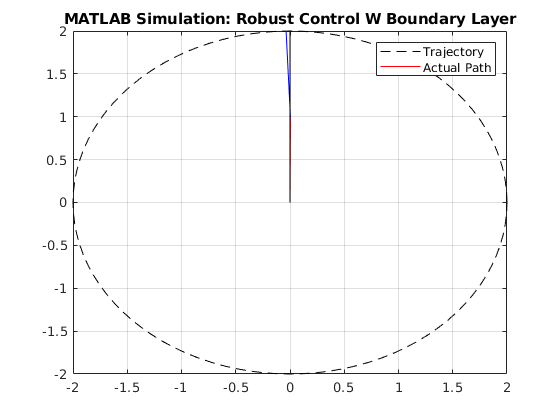

if speed_solve == false
    xAxisArrayXCoordinates = [-2 2];
    xAxisArrayYCoordinates = [0 0];
    yAxisArrayXCoordinates = [0 0];
    yAxisArrayYCoordinates = [-2 2];
    th = 0:pi / 50:2 * pi;
    xunit = ((al1 + al2) * cos(th));
    yunit = ((al1 + al2) * sin(th));
    for i = 1:1:t_size(1, 1)
        %Plotting Graph
        actuallink1XCoordinates = [0 actual_position(i, 1)];
        actuallink1YCoordinates = [0 actual_position(i, 2)];
        actuallink2XCoordinates = [actual_position(i, 1) actual_position(i, 3)];
        actuallink2YCoordinates = [actual_position(i, 2) actual_position(i, 4)];
        trajectorylink1XCoordinates = [0 trajectory_position(i, 1)];
        trajectorylink1YCoordinates = [0 trajectory_position(i, 2)];
        trajectorylink2XCoordinates = [trajectory_position(i, 1) trajectory_position(i, 3)];
        trajectorylink2YCoordinates = [trajectory_position(i, 2) trajectory_position(i, 4)];
        plot(xunit, yunit, 'k', 'LineStyle', '--'); % Draw Circular Axes
        hold on;
        plot(actuallink1XCoordinates, actuallink1YCoordinates, 'red')
        plot(actuallink2XCoordinates, actuallink2YCoordinates, 'blue')
        plot(trajectorylink1XCoordinates, trajectorylink1YCoordinates, 'black')
        plot(trajectorylink2XCoordinates, trajectorylink2YCoordinates, 'black')
        pause(0.1); % pause to see realtime animation. Given in seconds
        hold off;
    end
    legend('Trajectory', 'Actual Path')
    grid on;
    title(graph_title)

end

## Plot Trajectories

disp("Plotting System")
command = append('mkdir -p ','Photos/',system_type);
system(command);

The syntax of the command is incorrect. 


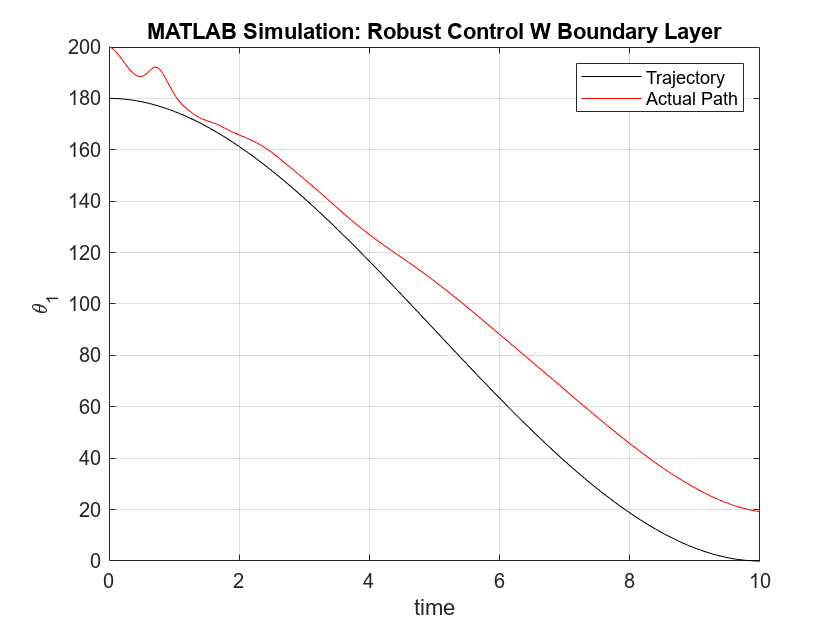

plot(time_points, rad2deg(theta_plot_points(:, 1)), 'black')
hold on;
plot(time_points, rad2deg(state_space_matrix(:, 1)), 'red')
legend('Trajectory', 'Actual Path')
hold off;
grid on;
xlabel('time');
ylabel('\theta_{1}')
title(graph_title)
saveas(gcf, append('Photos/',system_type,'/',system_type,"theta1.jpg"))

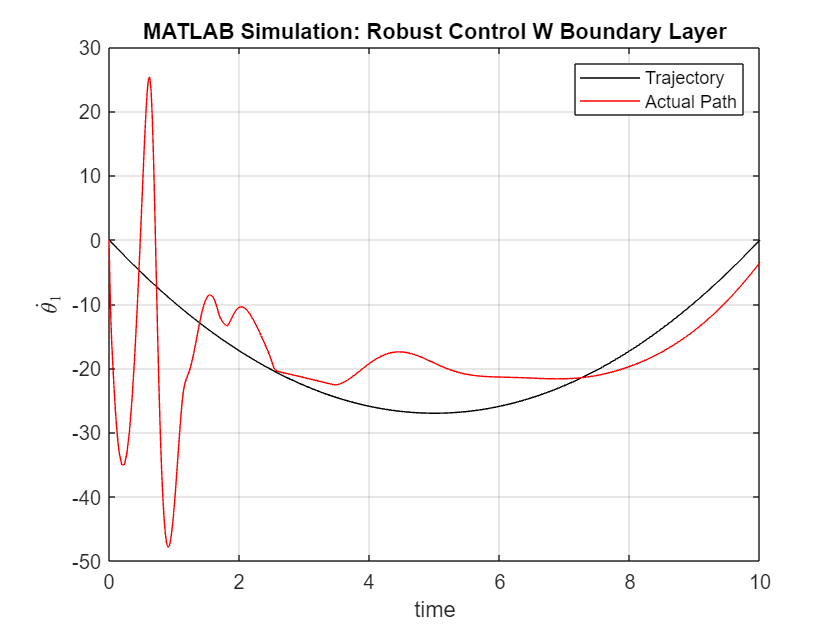


plot(time_points, rad2deg(theta_plot_points(:, 3)), 'black')
hold on;
plot(time_points, rad2deg(state_space_matrix(:, 3)), 'red')
legend('Trajectory', 'Actual Path')
hold off;
grid on;
xlabel('time');
ylabel('$\dot{\theta}_{1}$', 'Interpreter', 'latex')
title(graph_title)
saveas(gcf, append('Photos/',system_type,'/',system_type,"dtheta1.jpg"))

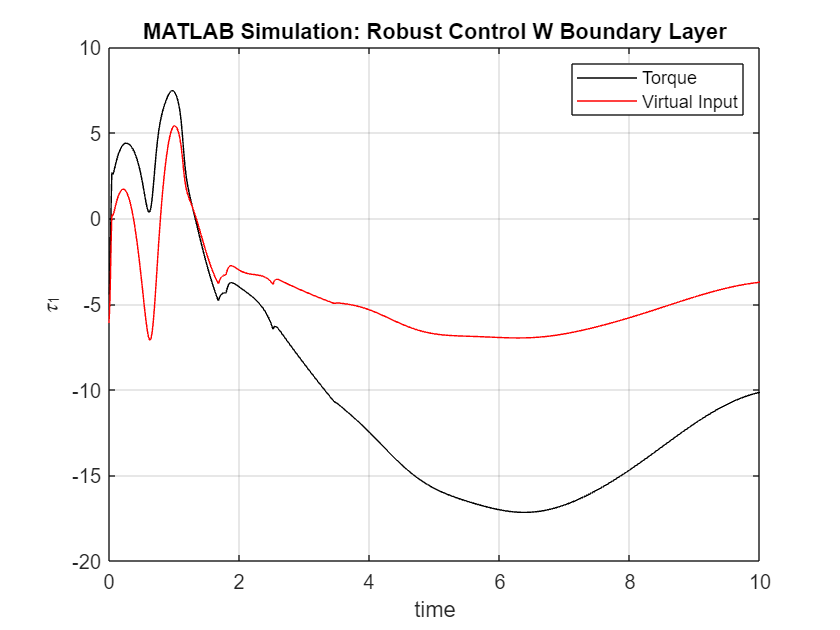


plot(time_points, system_input(:, 1), 'black')
hold on;
plot(time_points, virtual_input(:, 1), 'red')
hold off;
legend('Torque','Virtual Input')
grid on;
xlabel('time');
ylabel('\tau_{1}')
title(graph_title)
saveas(gcf, append('Photos/',system_type,'/',system_type,"control1.jpg"))

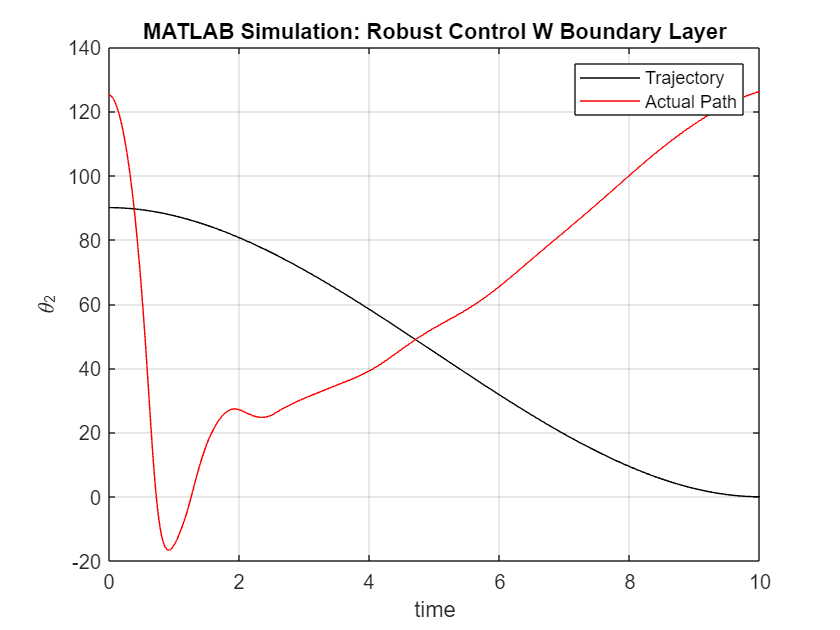


plot(time_points, rad2deg(theta_plot_points(:, 2)), 'black')
hold on;
plot(time_points, rad2deg(state_space_matrix(:, 2)), 'red')
legend('Trajectory', 'Actual Path')
hold off;
grid on;
xlabel('time');
ylabel('\theta_{2}')
title(graph_title)
saveas(gcf, append('Photos/',system_type,'/',system_type,"theta2.jpg"))

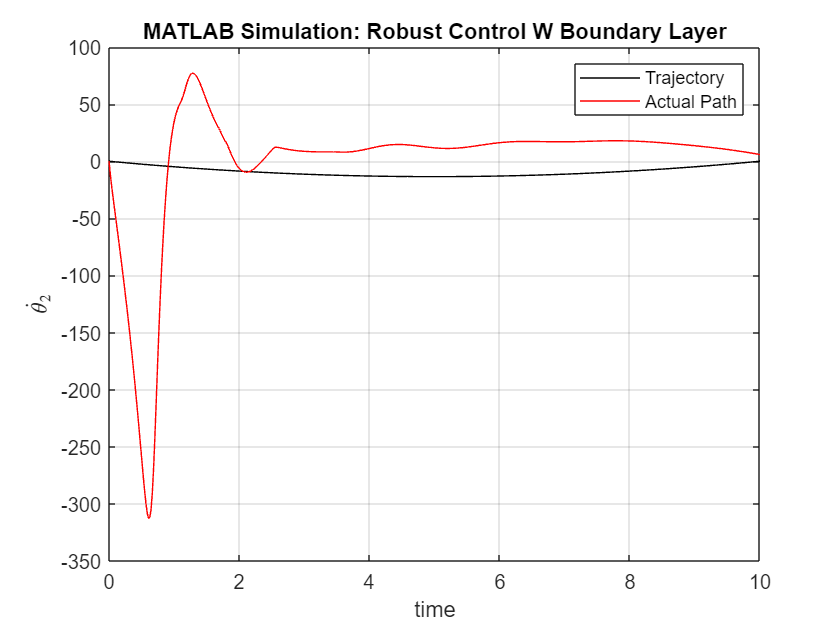


plot(time_points, rad2deg(theta_plot_points(:, 4)), 'black')
hold on;
plot(time_points, rad2deg(state_space_matrix(:, 4)), 'red')
legend('Trajectory', 'Actual Path')
hold off;
grid on;
xlabel('time');
ylabel('$\dot{\theta}_{2}$', 'Interpreter', 'latex')
title(graph_title)
saveas(gcf, append('Photos/',system_type,'/',system_type,"dtheta2.jpg"))

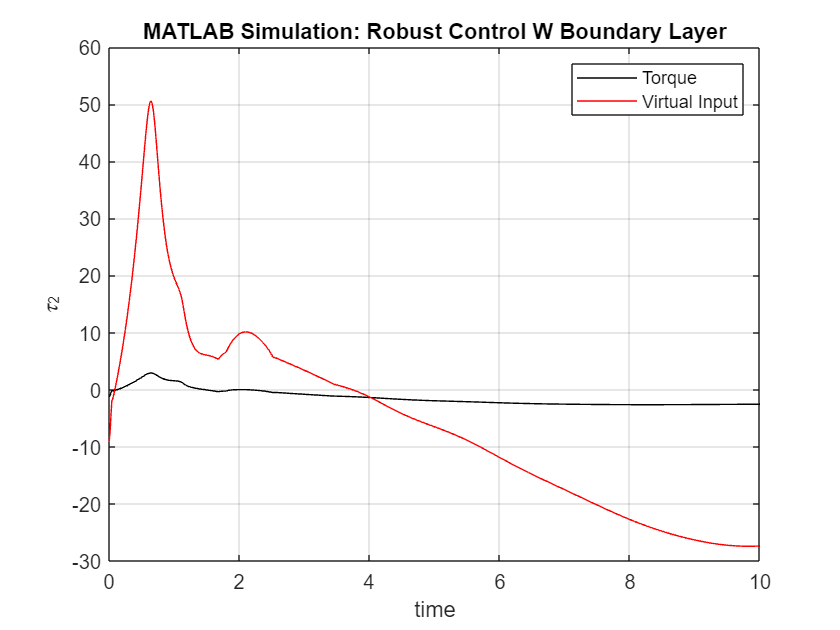


plot(time_points, system_input(:, 2), 'black')
hold on;
plot(time_points, virtual_input(:, 2), 'red')
hold off;
legend('Torque','Virtual Input')
grid on;
xlabel('time');
ylabel('\tau_{2}')
title(graph_title)
saveas(gcf, append('Photos/',system_type,'/',system_type,"control2.jpg"))